% image
imageFolder = 'imagemitsuba/cu_0.025/';
imageFiles = dir(fullfile(imageFolder, '*.mat')); % フォーマットに応じて変更
imgcnt = 2;
matFilePath = fullfile(imageFolder, imageFiles(imgcnt).name);
data = load(matFilePath);
%color space
cform1 = makecform('xyl2xyz')

cform1 = フィールドをもつ struct :
            c_func: @xyl2xyz
     ColorSpace_in: 'xyl'
    ColorSpace_out: 'xyz'
          encoding: 'double'
             cdata: [1×1 struct]


cform2 = makecform('xyz2xyl')

cform2 = フィールドをもつ struct :
            c_func: @xyz2xyl
     ColorSpace_in: 'xyz'
    ColorSpace_out: 'xyl'
          encoding: 'double'
             cdata: [1×1 struct]


%callibration
callibration_Path = 'callibration/'

callibration_Path = 'callibration/'

spectrum_data = readmatrix(fullfile(callibration_Path,'spectr.csv'));
c = tnt.RgbConverter(spectrum_data);
gamma_converter =load(fullfile(callibration_Path,"gamma_converter.mat")).gamma_converter;

%---Input xyY---

xyYImgin = data.image_np_xyY; 
LDR_Y = Reinhard(xyYImgin(:,:,3),1.0)*100;
lum_av = mean(xyYImgin(:))

lum_av = 0.3093

disp(lum_av)

    0.3093




xyYImgin(:,:,1) = 0.3127;
xyYImgin(:,:,2) = 0.3290;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform1);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);

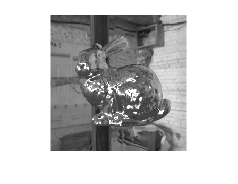

%}
%---Input xyY---
%---Input XYZ---
%{
xyzImgin = data.image_np_XYZ_900;
xyYImgin = applycform(xyzImgin,cform2);
LDR_Y = Reinhard(xyYImgin(:,:,3),1.0)*1;
xyYImgin(:,:,1) = 0.3127;
xyYImgin(:,:,2) = 0.3290;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform1);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);
%}
%---Input XYZ---
%---Input XYZ 2---
%{
xyzImgin = data.image_np;
xyYImgin = applycform(xyzImgin,cform2);
LDR_Y = Reinhard(xyYImgin(:,:,3),1.0)*1;
xyYImgin(:,:,1) = 0.3127;
xyYImgin(:,:,2) = 0.3290;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform1);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);
%}
%---Input XYZ 2---
%---Input rgb---
%{
rgbImgin = data.rgb_data;
xyzImgin = rgb2xyz(rgbImgin);
xyYImgin = applycform(xyzImgin,cform2);
LDR_Y = Reinhard(xyYImgin(:,:,3),1.0)*1;
xyYImgin(:,:,1) = 0.3127;
xyYImgin(:,:,2) = 0.3290;
xyYImgout = cat(3,xyYImgin(:,:,1),xyYImgin(:,:,2),LDR_Y);
xyzImgout = applycform(xyYImgout,cform1);
linear_rgb = c.xyz_to_linear_rgb(xyzImgout);
digital_rgb = gamma_converter.linear_rgb_to_digital_rgb(linear_rgb);
%}
%---Input rgb---

% confirm
xyzImgin = applycform(xyYImgin,cform1);
rgbImgin = xyz2rgb(xyzImgin);
rgbImgout = xyz2rgb(xyzImgout);
imshow(rgbImgin);

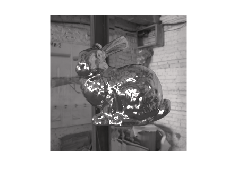

imshow(digital_rgb);

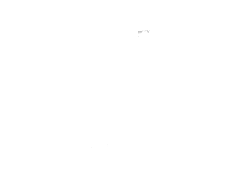

imshow(rgbImgout);